# 未取对直接拟合


clc, clear, close all
data = readmatrix("histogram_data1.csv");
logic = data(:, 1) > 0;
x = data(logic, 1)';
y = data(logic, 2)';

%MyPlot(x, y);
%MyScatter(x, log(y));

[fit, con ] = createFit_20241030_1729(x, y);
fit

fit =      常规模型:
     fit(x) = y_0+A_1*exp(-(x-x_0)/t_1)+A_2*exp(-(x-x_0)/t_2)
     系数(置信边界为 95%):
       A_1 =      0.0687  (-8.674e+04, 8.674e+04)
       A_2 =         100  (-1.51e+07, 1.51e+07)
       t_1 =       9.481  (9.317, 9.646)
       t_2 =        79.3  (-0.2718, 158.9)
       x_0 =       132.3  (-1.197e+07, 1.197e+07)
       y_0 =      0.9757  (-35.47, 37.42)

con

con = 包含以下字段的 struct :
           sse: 2.1174e+08
       rsquare: 0.9925
           dfe: 970
    adjrsquare: 0.9925
          rmse: 467.2108


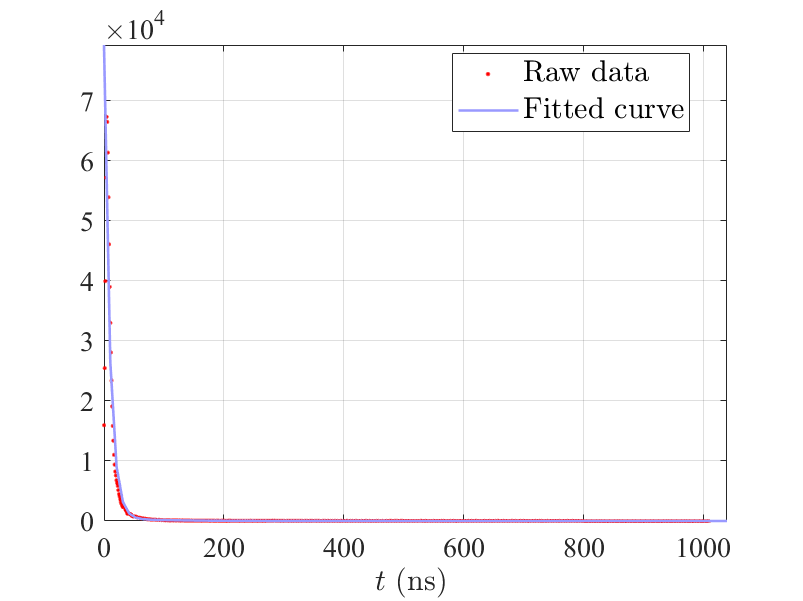


x_array = linspace(0, data(end, 1) + 30);
sca = MyScatter(x, y);
p1 = MyPlot_ax(sca.axes, x_array, fit(x_array)');
sca.scatter.scatter_1.SizeData = 30;
sca.scatter.scatter_1.MarkerEdgeColor = 'r';


%xline(0, 'Color', [0.5, 0.5, 0.5])
%yline(0, 'Color', [0.5, 0.5, 0.5])

p1.plot.plot_1.LineWidth = 1.3;
p1.label.x.String = '$t$ (ns) ';
p1.label.y.String = ' ';
p1.leg.String = ["Raw data"; "Fitted curve"];

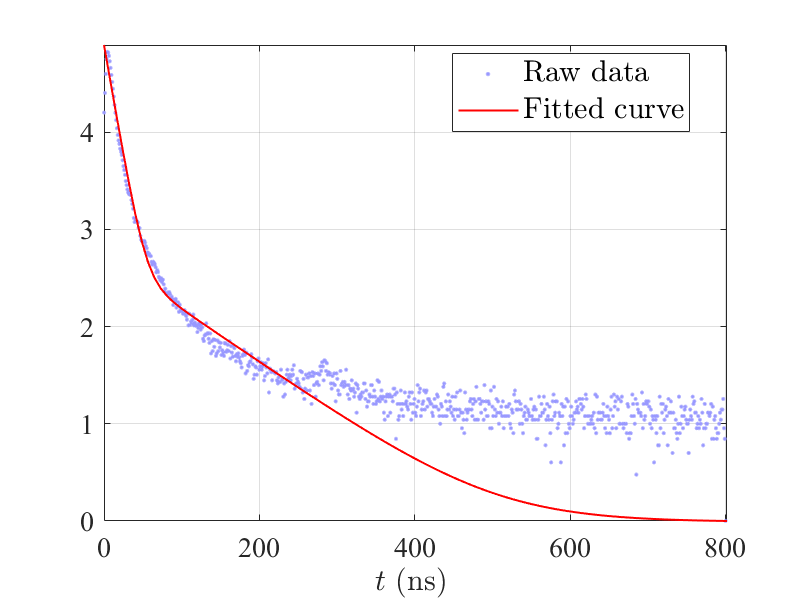


%MyExport_pdf
%MyExport_pdf_docked



x_array = linspace(0, 802);
sca = MyScatter(x, log(y)/log(10));
p1 = MyPlot_ax(sca.axes, x_array, log(fit(x_array)')/log(10));
MyColors = GetMyColors;
sca.scatter.scatter_1.SizeData = 30;
sca.scatter.scatter_1.MarkerEdgeColor = MyColors{1};

%xline(0, 'Color', [0.5, 0.5, 0.5])
%yline(0, 'Color', [0.5, 0.5, 0.5])

p1.plot.plot_1.LineWidth = 1;
p1.plot.plot_1.Color = 'r';
p1.label.x.String = '$t$ (ns) ';
p1.label.y.String = ' ';
p1.leg.String = ["Raw data"; "Fitted curve"];


%MyExport_pdf
%MyExport_pdf_docked


## 取对后再作拟合

data = readmatrix("histogram_data1.csv");
logic = data(:, 1) > 0;
x = data(logic, 1)';
y = data(logic, 2)';

%MyPlot(x, y);
%MyScatter(x, log(y));

[fit, console] = createFit_20241030_1901(x, log(y)/log(10));
fit
console

MyColors = GetMyColors;

x_array = linspace(0, data(end, 1) + 30);
sca = MyScatter(x, y);
p1 = MyPlot_ax(sca.axes, x_array, 10.^(fit(x_array))');
sca.scatter.scatter_1.SizeData = 30;
sca.scatter.scatter_1.MarkerEdgeColor = MyColors{1};

p1.plot.plot_1.LineWidth = 1;
p1.plot.plot_1.Color = 'r';
p1.label.x.String = '$t$ (ns) ';
p1.label.y.String = ' ';
p1.leg.String = ["Raw data"; "Fitted curve"];

x_array = linspace(0, 802);
sca = MyScatter(x, log(y)/log(10));
p1 = MyPlot_ax(sca.axes, x_array, fit(x_array)');

sca.scatter.scatter_1.SizeData = 30;
sca.scatter.scatter_1.MarkerEdgeColor = MyColors{1};

%xline(0, 'Color', [0.5, 0.5, 0.5])
%yline(0, 'Color', [0.5, 0.5, 0.5])

p1.plot.plot_1.LineWidth = 1;
p1.plot.plot_1.Color = 'r';
p1.label.x.String = '$t$ (ns) ';
p1.label.y.String = ' ';
p1.leg.String = ["Raw data"; "Fitted curve"];

## 取对后再拟合，对数坐标系

data = readmatrix("histogram_data1.csv");
logic = data(:, 1) > 0;
x = data(logic, 1)';
y = data(logic, 2)';
y_lg = log(y)/log(10);

%MyPlot(x, y);
%MyScatter(x, log(y));

[fit, console] = createFit_20241030_1901(x, log(y)/log(10));

fit

fit =      常规模型:
     fit(x) = log(y_0+A_1*exp(-(x-x_0)/t_1)+A_2*exp(-(x-x_0)/t_2))
     系数(置信边界为 95%):
       A_1 =      0.9675  (-2.289e+05, 2.289e+05)
       A_2 =       5.255  (-2.102e+05, 2.102e+05)
       t_1 =       20.21  (19.89, 20.53)
       t_2 =       119.5  (117.3, 121.7)
       x_0 =       92.86  (-4.781e+06, 4.781e+06)
       y_0 =        2.92  (2.908, 2.931)

console

console = 包含以下字段的 struct :
           sse: 0.5476
       rsquare: 0.9987
           dfe: 768
    adjrsquare: 0.9986
          rmse: 0.0267


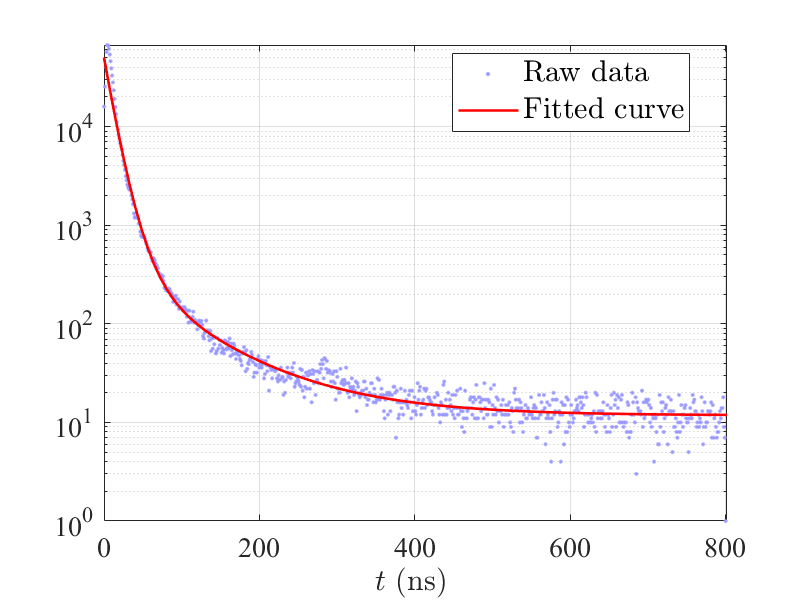


MyColors = GetMyColors;

x_array = linspace(0, 802);
sca = MyScatter(x((y>0)), y((y>0)));
p1 = MyPlot_ax(sca.axes, x_array, 10.^(fit(x_array))');
sca.scatter.scatter_1.SizeData = 30;
sca.scatter.scatter_1.MarkerEdgeColor = MyColors{1};

p1.plot.plot_1.LineWidth = 1.3;
p1.plot.plot_1.Color = 'r';
p1.label.x.String = '$t$ (ns) ';
p1.label.y.String = ' ';
p1.leg.String = ["Raw data"; "Fitted curve"];

set(sca.axes, 'YScale', 'log');

## 舍弃极大峰及之前的数据点，取 lg 后再拟合，对数坐标系

data = readmatrix("histogram_data1.csv");
logic = data(:, 1) > 0;
x = data(54:end, 1)';
y = data(54:end, 2)';
y_lg = log(y)/log(10);

%MyPlot(x, y);
%MyScatter(x, log(y));

[fit, console] = createFit_20241030_1901(x, log(y)/log(10));

fit

fit =      常规模型:
     fit(x) = log(y_0+A_1*exp(-(x-x_0)/t_1)+A_2*exp(-(x-x_0)/t_2))
     系数(置信边界为 95%):
       A_1 =      0.8658  (-2.133e+05, 2.133e+05)
       A_2 =       5.265  (-2.164e+05, 2.164e+05)
       t_1 =       19.82  (19.47, 20.17)
       t_2 =       118.8  (116.7, 120.9)
       x_0 =       93.62  (-4.883e+06, 4.883e+06)
       y_0 =       2.921  (2.91, 2.932)

console

console = 包含以下字段的 struct :
           sse: 0.5236
       rsquare: 0.9985
           dfe: 763
    adjrsquare: 0.9985
          rmse: 0.0262



MyColors = GetMyColors;

x_array = linspace(0, 802);
sca = MyScatter(data(:,1)', data(:,2)');
p1 = MyPlot_ax(sca.axes, x_array, 10.^(fit(x_array))');
sca.scatter.scatter_1.SizeData = 30;
sca.scatter.scatter_1.MarkerEdgeColor = MyColors{1};
sca.scatter.scatter_1.MarkerEdgeColor = 'b'

sca = 包含以下字段的 struct :
        fig: [1×1 Figure]
       axes: [1×1 Axes]
    scatter: [1×1 struct]
      label: [1×1 struct]
        leg: [1×1 Legend]


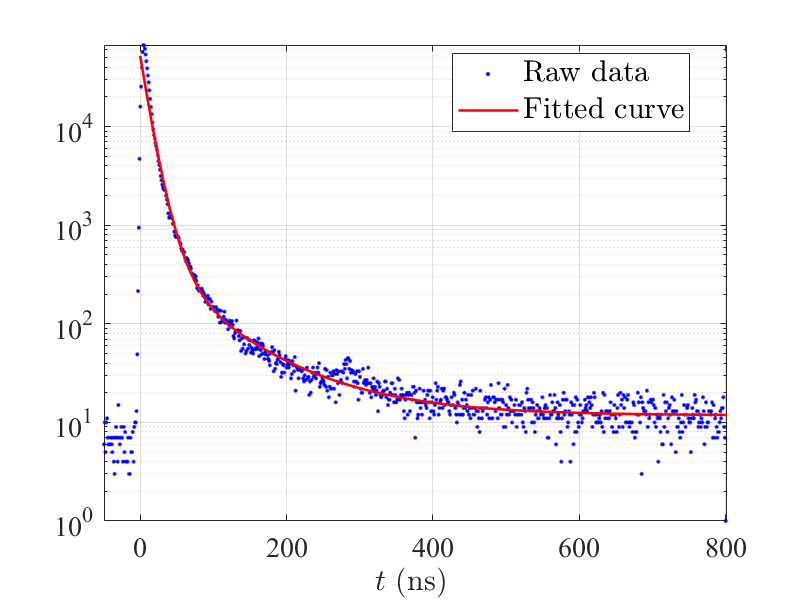


p1.plot.plot_1.LineWidth = 1.3;
p1.plot.plot_1.Color = 'r';
p1.label.x.String = '$t$ (ns) ';
p1.label.y.String = ' ';
p1.leg.String = ["Raw data"; "Fitted curve"];

set(sca.axes, 'YScale', 'log');
xlim([data(1,1), 802])


%MyExport_pdf_docked

## 优度与残差分析

logic = data(:, 1) > 0;
analysis_x = data(logic, 1)';
analysis_y = data(logic, 2)';
analysis_y_lg = log(analysis_y)/log(10);
analysis_y_lg_hat = fit(analysis_x)';

stc = MyErrorAnalyzer_discrete(analysis_y_lg, analysis_y_lg_hat, 1);

------------------------------------------------------------------
Data size:     1 * 976
Y_bar        = -Inf
Y_hat_bar    = 1.42430086
  
R2         = NaN
R2_adj     = NaN
MyR2         = NaN
MyR2_adj     = NaN
MAPE         = NaN
MyMAPE       = NaN
RMSE         = Inf
fitness      = NaN
fitness_adj  = NaN
RMSLE        = Inf+Infi
------------------------------------------------------------------


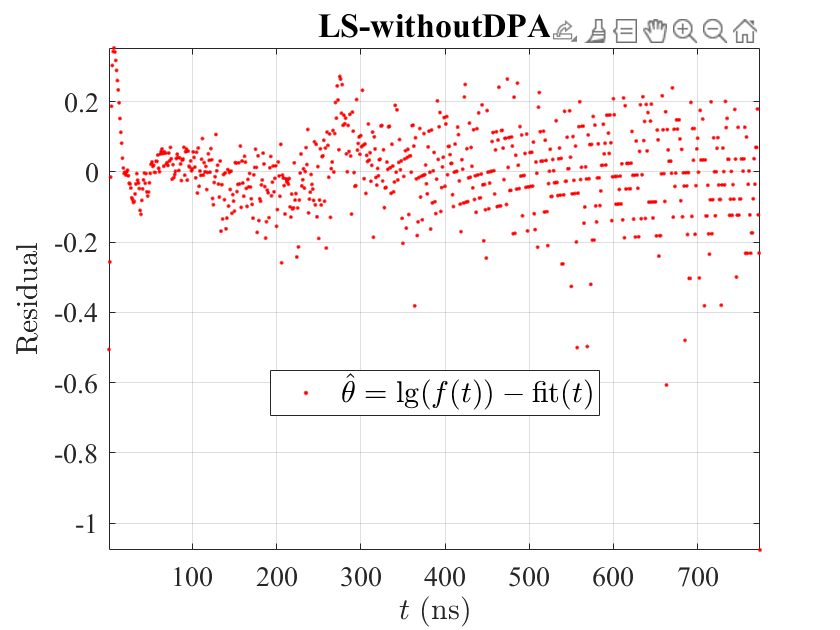

stc.ResidualScatter.label.x.String = '$t$ (ns)';
stc.ResidualScatter.label.y.String = 'Residual';
stc.ResidualScatter.leg.String = '$\hat{\theta} = \lg (f(t)) - \mathrm{fit}(t)$';
stc.ResidualScatter.axes.Title.String = 'LS-withoutDPA';
stc.ResidualScatter.axes.Title.Interpreter = 'none';
%MyPlot(x, 10.^fit(x)')
MyExport_pdf_docked

## 数据2，未取对拟合极值峰

data = readmatrix("histogram_data.csv");
logic = data(:, 1) > 0;
x = data(logic, 1)';
y = data(logic, 2)';

%MyPlot(x, y);
%MyScatter(x, log(y));

[fit, console] = createFit_20241030_2024(x, y);
fit
console

MyColors = GetMyColors;

x_array = [linspace(0.2105, 5, 100), linspace(5, 802, 100)];
sca = MyScatter(x((y>0)), y((y>0)));
p1 = MyPlot_ax(sca.axes, x_array, fit(x_array)');
sca.scatter.scatter_1.SizeData = 30;
sca.scatter.scatter_1.MarkerEdgeColor = MyColors{1};

p1.plot.plot_1.LineWidth = 0.5;
p1.plot.plot_1.Color = 'r';
p1.label.x.String = '$t$ (ns) ';
p1.label.y.String = ' ';
p1.leg.String = ["Raw data"; "Fitted curve"];

%set(sca.axes, 'YScale', 'log');

global A_1 A_2 t_1 t_2 x_0 y_0
A_1 = 0.5821
A_2 = 0.3564
t_1 = 12.73
t_2 = 73.33
x_0 = 0.4
y_0 = 11.29

Y = @(x) y_0 + A_1*exp(-(x-x_0)/t_1) + A_2*exp(-(x-x_0)/t_2)
X = linspace(0, 1000)

% 假设已经有一些数据和图形
x = 10.^(1:4); % 创建一个向量，范围从 10 到 10^4
y = x.^2;
plot(x, y);

% 设置 x 轴为对数刻度
set(gca, 'XScale', 'log');

% 或者，如果你想要同时设置 x 轴和 y 轴
set(gca, 'XScale', 'log', 'YScale', 'log');